## Data Import and Setup

data = readtable("HW3_data.xlsx");

% Transpose data so Observations are rows and Genes are columns
data1 = rows2vars(data,"VariableNamesSource","ID_REF");

% Create X and Y by removing non-numerical rows from data1. 
X = cell2mat(data1{3:end,2:end-1});
Xz = zscore(X);
Y = cell2mat(data1{3:end,"SurvivalDays"});
Yz = zscore(Y);

## Find Top 100 Genes (p-value)

% Extract r and p-value data
[r, pval] = corr(X,Y);

% Identify top 100 correlated genes based on p-value
[gene_pval,gene_index] = mink(abs(pval),100);
var_names = data1.Properties.VariableNames(gene_index+1)

var_names = 1×100 cell array
    {'A_23_P342744'}    {'A_24_P246891'}    {'A_23_P24535'}    {'A_23_P75362'}    {'A_32_P76399'}    {'A_23_P102973'}    {'A_23_P133332'}    {'A_23_P257335'}    {'A_24_P192988'}    {'A_23_P151106'}    {'A_23_P120970'}    {'A_24_P810290'}    {'A_23_P131825'}    {'A_23_P206684'}    {'A_32_P32061'}    {'A_23_P79122'}    {'A_23_P368278'}    {'A_23_P13344'}    {'A_23_P401709'}    {'A_24_P67308'}    {'A_23_P430381'}    {'A_24_P297119'}    {'A_23_P320530'}    {'A_24_P649282'}    {'A_23_P27229'}    {'A_24_P766208'}    {'A_23_P147255'}    {'A_24_P380679'}    {'A_23_P256773'}    {'A_23_P75529'}    {'A_32_P230828'}    {'A_23_P104641'}    {'A_23_P101871'}    {'A_24_P63563'}    {'A_23_P436369'}    {'A_23_P325690'}    {'A_24_P216765'}    {'A_23_P359245'}    {'A_23_P57370'}    {'A_24_P7085'}    {'A_23_P119295'}    {'A_23_P123555'}    {'A_23_P304386'}    {'A_32_P49616'}    {'A_24_P16340'}    {'A_23_P65068'}    {'A_24_P12932'}    {'A_23_P251680'}    {'A_24_P91472'}    {'A_2

% Create new data set w/ 100 genes plus Survival Days data
data_rev = data1(:,[gene_index+1;end]);

% Check that new matrix looks correct
head(data_rev)

ans = 8×101 table
           A_23_P342744            A_24_P246891                 A_23_P24535                                  A_23_P75362                                           A_32_P76399                                         A_23_P102973                                A_23_P133332                                             A_23_P257335                                            A_24_P192988                A_23_P151106                      A_23_P120970                                             A_24_P810290                                   A_23_P131825                               A_23_P206684                                     A_32_P32061                                        A_23_P79122                  

% Write new matrix to csv file for future use
writetable(data_rev,"Top 100 Genes.csv")

% Create new X and Y matrices

X_100 = cell2mat(data_rev{3:end,1:100});
Y_100 = cell2mat(data_rev{3:end,end});

## Hold Out Validation Model

### Using Top 20 Correlated Genes from Training Set

% Create X and Y training/test sets from 100 genes
[trainInd,~,testInd] = dividerand(size(X_100,1),0.7,0,0.3);
Xtrain = X_100(trainInd,:);
Xtest = X_100(testInd,:);
Ytrain = Y_100(trainInd,:);
Ytest = Y_100(testInd,:);

% Find top 20 correlated genes with training data
r_100 = corr(Xtrain,Ytrain);
[r_20,index_20] = maxk(abs(r_100),20);

% Create new training and test predictor data sets with top 20 genes 
Xtrain_20 = Xtrain(:,index_20);
Xtest_20 = Xtest(:,index_20);

mdl_20 = fitlm(Xtrain_20,Ytrain)

mdl_20 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate       SE         tStat         pValue  
                   _________    ______    ___________    __________

    (Intercept)       536.06     69.11         7.7566    1.3465e-07
    x1               -22.317    63.378       -0.35213       0.72825
    x2                84.066    49.352         1.7034       0.10325
    x3                180.93     89.93         2.0119      0.057239
    x4                38.562    169.01        0.22817       0.82172
    x5               -43.673    51.844        -0.8424       0.40906
    x6              

Ypred = predict(mdl_20,Xtest_20);
r_mdl = corr(Ytest,Ypred)

r_mdl = 0.2431

r2_mdl = r_mdl^2

r2_mdl = 0.0591

RMSE = sqrt(mean((Ypred-Ytest).^2))   

RMSE = 418.5823

avg_error = mean(abs(Ypred-Ytest)./Ytest*100)

avg_error = 143.5671

## Hold Out Model w/ For Loop

### Top 20 Correlated Genes are Reselected Each Iteration

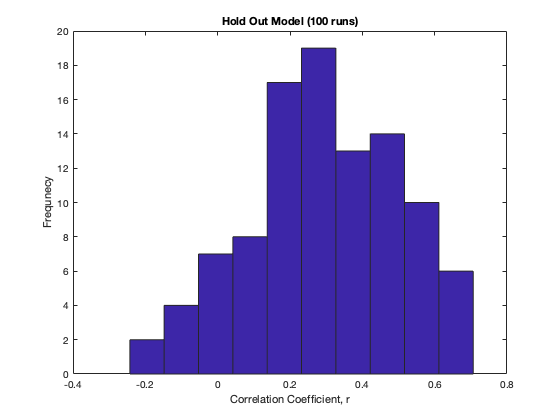

r_mdl = zeros(100,1);
for j = 1:100
    % Create X and Y training/test sets from 100 genes
    [trainInd,~,testInd] = dividerand(size(X_100,1),0.7,0,0.3);
    Xtrain = X_100(trainInd,:);
    Xtest = X_100(testInd,:);
    Ytrain = Y_100(trainInd,:);
    Ytest = Y_100(testInd,:);
    
    % Find top 20 correlated genes with training data
    r_100 = corr(Xtrain,Ytrain);
    [r_20,index_20] = maxk(abs(r_100),20);
    
    % Create new training and test predictor data sets with top 20 genes 
    Xtrain_20 = Xtrain(:,index_20);
    Xtest_20 = Xtest(:,index_20);
    
    mdl_20 = fitlm(Xtrain_20,Ytrain);
    
    Ypred = predict(mdl_20,Xtest_20);
    
    r_mdl(j) = corr(Ytest,Ypred);
    %r2_mdl = r_mdl^2
    %RMSE = sqrt(mean((Ypred-Ytest).^2))   
    %avg_error = mean(abs(Ypred-Ytest)./Ytest*100)
end

hist(r_mdl)
xlabel("Correlation Coefficient, r")
ylabel("Frequnecy")
title("Hold Out Model (100 runs)")

## K-fold Cross Validation Model

% For K-fold model, using top 20 correlated genes from entire data set (not
% just the training set, as the 20 genes would change each iteration)

r_100_kfold = corr(X_100,Y_100);
[r_20_kfold,index_20_kfold] = maxk(abs(r_100_kfold),20);


indices = crossvalind('kfold',size(X_100,1),5);
RMSE_kfold = zeros(5,1);
corr_kfold = zeros(5,1);
avg_error = zeros(5,1);
X_kfold = X_100(:,index_20_kfold);

% Run through loop 5 times and assign iteration number to i. Identify rows
% in indices equal to i and assign to test; assign remaining rows to train.
for i = 1:5  
    test = (indices == i);   
    train = ~test;   
    
    % Extract train rows from X and Y. Create linear model with train data.
    Xtrain = X_kfold(train,:);    
    Ytrain = Y_100(train,:);   
    model = fitlm(Xtrain,Ytrain);  
    
    %Extract test rows from X and Y 
    Xtest = X_kfold(test,:);   
    Ytest = Y_100(test,:);   
    
    % Predict Y values from model. Calculate stat parameters and assign
    % to index i of variables
    Ypred = predict(model,Xtest);   
    corr_kfold(i) = corr(Ytest,Ypred);   
    RMSE_kfold(i) = sqrt(mean((Ypred-Ytest).^2));   
    avg_error(i) = mean(abs(Ypred-Ytest)./Ytest*100);
end

mean(corr_kfold)

ans = 0.4558


mean(RMSE_kfold)

ans = 338.8842


mean(abs(avg_error))

ans = 81.9366

## K-fold Cross Validation w/ For Loop


corr_kfold = zeros(5,100);
X_kfold = X_100(:,index_20_kfold);


for j = 1:100
    indices = crossvalind('kfold',size(X_100,1),5);
    %RMSE_kfold = zeros(5,1);
    %corr_kfold = zeros(5,1);
    %avg_error = zeros(5,1);
    
    % Run through loop 5 times and assign iteration number to i. Identify rows
    % in indices equal to i and assign to test; assign remaining rows to train.
    for i = 1:5  
        test = (indices == i);   
        train = ~test;   
        
        % Extract train rows from X and Y. Create linear model with train data.
        Xtrain = X_kfold(train,:);    
        Ytrain = Y_100(train,:);   
        model = fitlm(Xtrain,Ytrain);  
        
        %Extract test rows from X and Y 
        Xtest = X_kfold(test,:);   
        Ytest = Y_100(test,:);   
        
        % Predict Y values from model. Calculate stat parameters and assign
        % to index i of variables
        Ypred = predict(model,Xtest);   
        corr_kfold(i,j) = corr(Ytest,Ypred);   
       % RMSE_kfold(i) = sqrt(mean((Ypred-Ytest).^2));   
        %avg_error(i) = mean(abs(Ypred-Ytest)./Ytest*100);
    end

end

mean_corr = mean(corr_kfold);
mean(mean_r,"all")

ans = 0.4067

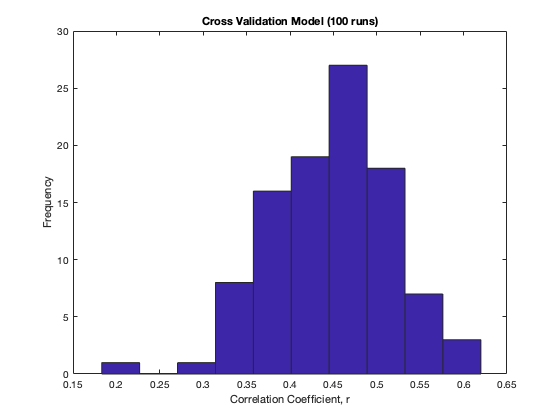

hist(mean_corr)
xlabel("Correlation Coefficient, r")
ylabel("Frequency")
title("Cross Validation Model (100 runs)")